tstart = 0;
tend = 1;
fs = 100;
ts = 1/fs;
t = tstart : ts : tend-ts

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


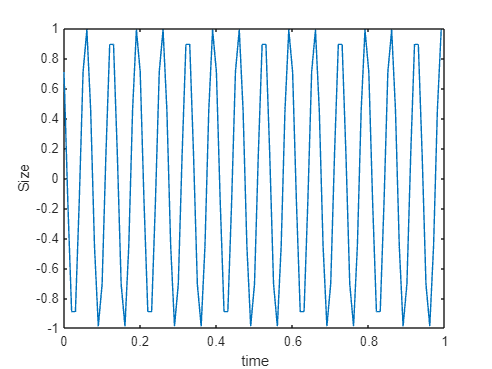


x1 = cos(30*pi*t + pi/4);
plot (t,x1)
xlabel 'time'
ylabel 'Size'

y = fftshift(fft(x1));
n = 100

n = 100

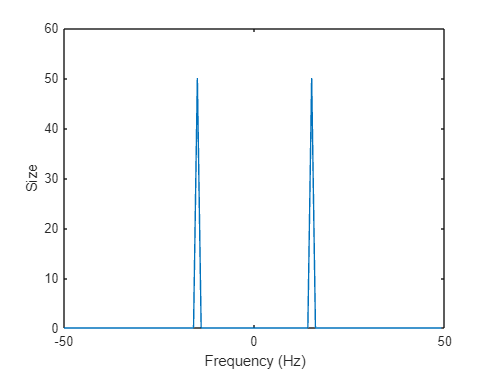

f = -fs/2 : fs/n : fs/2 - fs/n;
plot(f,abs(y))
xlabel 'Frequency (Hz)'
ylabel 'Size'

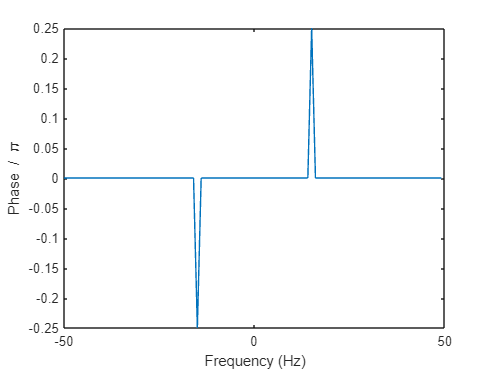

tol = 1e-6;
y(abs(y) < tol) = 0;
theta = angle(y);
plot(f,theta/pi)
xlabel 'Frequency (Hz)'
ylabel 'Phase / \pi'